Pause 15s...
Capturing image


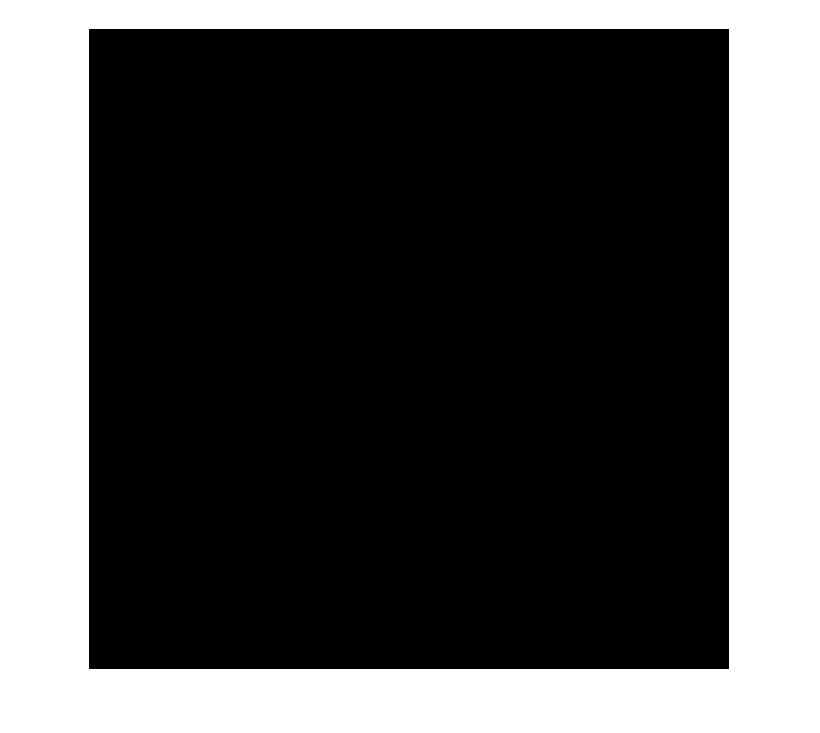

Dot indexing is not supported for variables of this type.

Error in EGB339_21S2_19/extractData (line 273)
        if redProps(i).Area <= 30

Error in EGB339_21S2_19 (

% sim = coppeliaRobot();
% ---
init_image = imread("init_image7.jpg");
dest_image = imread("init_image1.jpg");
% ---

a = EGB339_21S2_19(sim, init_image, dest_image)

## ROBOT ARM

cylinderPos = [init_xy(1,1) init_xy(2,1); init_xy(1,2) init_xy(2,2); init_xy(1,3) init_xy(2,3)]
setCylinderPosition(sim, cylinderPos);
q0 = [0 0 0 0 0];
% ---


setJointPositions(sim, q0);
pause(2);
for i = 1:3
    % Reach to initial position
    init_xy(:,i)
    q_new = reach(sim, init_xy(1,i), init_xy(2,i));
    setSuctionCup(sim, 1);
    
    % Back to origin
    q_current = getJointPositions(sim);
    q_mid = jtraj(q_current, q0, 10);
    for q=q_mid'
        setJointPositions(sim, q);
    end
    
    % Reach to destination position
    dest_xy(:,i)
    reach(sim, dest_xy(1,i), dest_xy(2,i));
    setSuctionCup(sim, 0);
    
    % Back to origin
    q_current = getJointPositions(sim);
    q_mid = jtraj(q_current, q0, 10);
    for q=q_mid'
        setJointPositions(sim, q);
    end
end